# Machine Learning: Programming Exercise 1

## Linear Regression

In this exercise, you will implement linear regression and get to see it work on data.

### Files needed for this exercise

- `ex1.mlx` - MATLAB Live Script that steps you through the exercise

- ex1data1.txt - Dataset for linear regression with one variable

- ex1data2.txt - Dataset for linear regression with multiple variables

- `submit.m` - Submission script that sends your solutions to our servers

- *`warmUpExercise.m` - Simple example function in MATLAB

- *`plotData.m` - Function to display the dataset

- *`computeCost.m` - Function to compute the cost of linear regression

- *`gradientDescent.m` - Function to run gradient descent

- **`computeCostMulti.m` - Cost function for multiple variables

- **`gradientDescentMulti.m` - Gradient descent for multiple variables

- **`featureNormalize.m `- Function to normalize features

- **`normalEqn.m` - Function to compute the normal equations

****indicates files you will need to complete***

*****indicates optional exercises***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex1' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

.                          computeCostMulti.m         ex1data1.txt               gradientDescent.m          normalEqn.m                submit.m                   
..                         ex1.mlx                    ex1data2.txt               gradientDescentMulti.m     plotData.m                 token.mat                  
computeCost.m              ex1_companion.mlx          featureNormalize.m         lib                        squareAndCubeThisNumber.m  warmUpExercise.m           



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README.mlx` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README.mlx` and have checked for an existing solution before seeking help on the discussion forums.

## 1. A simple MATLAB function

The first part of this script gives you practice with MATLAB syntax and the homework submission process. In the file `warmUpExercise.m`, you will find the outline of a MATLAB function. Modify it to return a 5 x 5 identity matrix by filling in the following code:

When you are finished, save `warmUpExercise.m`, then run the code contained in this section to call `warmUpExercise().` 

**5x5 Identity Matrix:**

warmUpExercise()

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


You should see output similar to the following:

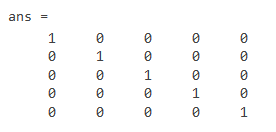

You can toggle between right-hand-side output and in-line output for printing results and displaying figures inside a Live Script by selecting the appropriate box in the upper right of the Live Editor window. 

### 1.1 Submitting Solutions

After completing a part of the exercise, you can submit your solutions for that section by running the section of code below, which calls the `submit.m` script. Your score for each section will then be displayed as output. **Enter your login and your unique submission token *****inside the command window***** when prompted. For future submissions of this exercise, you will only be asked to confirm your credentials.** Your submission token for each exercise is found in the corresponding homework assignment course page. New tokens can be generated if you are experiencing issues with your current token. You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter your login and token when prompted.*

## 2. Linear regression with one variable

In this part of this exercise, you will implement linear regression with one variable to predict profits for a food truck. Suppose you are the CEO of a restaurant franchise and are considering different cities for opening a new outlet. The chain already has trucks in various cities and you have data for profits and populations from the cities. You would like to use this data to help you select which city to expand to next.

The file `ex1data1.txt` contains the dataset for our linear regression problem. The first column is the population of a city and the second column is the profit of a food truck in that city. A negative value for profit indicates a loss. This script has already been set up to load this data for you.

### 2.1 Plotting the data

Before starting on any task, it is often useful to understand the data by visualizing it. For this dataset, you can use a scatter plot to visualize the data, since it has only two properties to plot (profit and population). Many other problems that you will encounter in real life are multi-dimensional and can't be plotted on a 2-d plot.

Run the code below to load the dataset from the data file into the variables X and y:

data = load('ex1data1.txt'); % read comma separated data
X = data(:, 1); y = data(:, 2);

Your job is to complete `plotData.m` to draw the plot; modify the file and fill in the following code:

Once you are finished, save `plotData.m,` and execute the code in this section which will call `plotData`. 

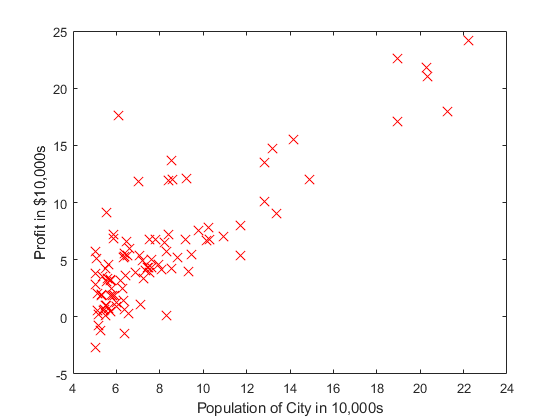

plotData(X,y)

The resulting plot should appear as in Figure 1 below:

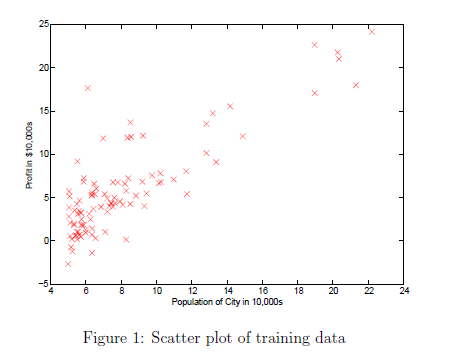

To learn more about the `plot` command, you can run the command `help plot` at the command prompt, type `plot()` inside the MATLAB Live Editor and click on the "(?)" tooltip, or you can search the [MATLAB documentation](https://www.mathworks.com/help/matlab/) for "plot". Note that to change the markers to red x's in the plot, we used the option: **'**`rx'` together with the `plot` command, i.e., 

### 2.2 Gradient Descent

In this section, you will fit the linear regression parameters to our dataset using gradient descent.

#### 2.2.1 Update Equations

The objective of linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \;$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


Recall that the parameters of your model are the $\theta$ values. These are the values you will adjust to minimize cost $J(\theta)$. One way to do this is to use the batch gradient descent algorithm. In batch gradient descent, each iteration performs the update


$$\theta_j :=\theta_j -\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\;\;\;\;\;\left(\textrm{simultaneously}\;\textrm{update}\;\theta_{j\;} \;\textrm{for}\;\textrm{all}\;j\right)$$


With each step of gradient descent, your parameters $j$ come closer to the optimal values that will achieve the lowest cost $J(\theta)$.

**Implementation Note:** We store each example as a row in the the `X` matrix in MATLAB. To take into account the intercept term ($\theta_0$), we add an additional first column to `X` and set it to all ones. This allows us to treat $\theta_0$ as simply another 'feature'.

#### 2.2.2 Implementation

In this script, we have already set up the data for linear regression. In the following lines, we add another dimension to our data to accommodate the $\theta_0$ intercept term. Run the code below to initialize the parameters to 0 and the learning rate `alpha` to 0.01. 

m = length(X); % number of training examples
X = [ones(m,1),data(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
iterations = 1500;
alpha = 0.01;

#### 2.2.3 Computing the cost $\mathit{\mathbf{J}}\left(\theta \right)$

As you perform gradient descent to minimize the cost function $J\left(\theta \right)$, it is helpful to monitor the convergence by computing the cost. In this section, you will implement a function to calculate $J\left(\theta \right)$ so you can check the convergence of your gradient descent implementation.

    Your next task is to complete the code in the file `computeCost.m`, which is a function that computes $J\left(\theta \right)$. As you are doing this, remember that the variables `X` and `y` are not scalar values, but matrices whose rows represent the examples from the training set.

    Once you have completed the function definition, run this section. The code below will call `computeCost` once using $\theta$ initialized to zeros, and you will see the cost printed to the screen. You should expect to see a cost of 32.07 for the first output below:

% Compute and display initial cost with theta all zeros
computeCost(X, y, theta)

J = 32.0727

ans = 32.0727

Next we call `computeCost` again, this time with non-zero `theta` values as an additional test. You should expect to see an output of 54.24 below:

% Compute and display initial cost with non-zero theta
computeCost(X, y,[-1; 2])

J = 54.2425

ans = 54.2425

If the outputs above match the expected values, you can submit your solution for assessment. If the outputs do not match or you receive an error, check your cost function for mistakes, then rerun this section once you have addressed them.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.2.4 Gradient descent

Next, you will implement gradient descent in the file `gradientDescent.m`. The loop structure has been written for you, and you only need to supply the updates to $\theta$ within each iteration.

    As you program, make sure you understand what you are trying to optimize and what is being updated. Keep in mind that the cost $J\left(\theta \right)$ is parameterized by the vector $\theta$, not $X$ and $y$. That is, we minimize the value of $J\left(\theta \right)$ by changing the values of the vector $\theta$, not by changing $X$ or $y$. Refer to the equations given earlier and to the video lectures if you are uncertain.

A good way to verify that gradient descent is working correctly is to look at the value of `J` and check that it is decreasing with each step. The starter code for `gradientDescent.m` calls `computeCost` on every iteration and prints the cost. Assuming you have implemented gradient descent and `computeCost` correctly, your value of $J\left(\theta \right)$ should never increase, and should converge to a steady value by the end of the algorithm.

    After you are finished, run this execute this section. The code below will use your final parameters to plot the linear fit. The result should look something like Figure 2 below:

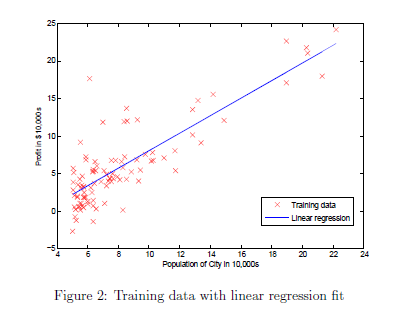    

    Your final values for $\theta$ will also be used to make predictions on profits in areas of 35,000 and 70,000 people.

% Run gradient descent:
% Compute theta
theta = gradientDescent(X, y, theta, alpha, iterations);

s =    -5.8391
  -65.3288


J = 6.7372

s =    -0.4500
  -11.6721


J = 5.9316

s =     0.5069
   -2.1338


J = 5.9012

s =     0.6759
   -0.4382


J = 5.8952

s =     0.7049
   -0.1366


J = 5.8901

s =     0.7090
   -0.0829


J = 5.8850

s =     0.7087
   -0.0733


J = 5.8799

s =     0.7076
   -0.0715


J = 5.8749

s =     0.7063
   -0.0710


J = 5.8698

s =     0.7051
   -0.0708


J = 5.8648

s =     0.7038
   -0.0707


J = 5.8598

s =     0.7025
   -0.0706


J = 5.8548

s =     0.7013
   -0.0705


J = 5.8499

s =     0.7000
   -0.0703


J = 5.8449

s =     0.6987
   -0.0702


J = 5.8400

s =     0.6975
   -0.0701


J = 5.8351

s =     0.6962
   -0.0699


J = 5.8302

s =     0.6950
   -0.0698


J = 5.8253

s =     0.6937
   -0.0697


J = 5.8205

s =     0.6925
   -0.0696


J = 5.8156

s =     0.6912
   -0.0694


J = 5.8108

s =     0.6900
   -0.0693


J = 5.8060

s =     0.6887
   -0.0692


J = 5.8012

s =     0.6875
   -0.0691


J = 5.7965

s =     0.6863
   -0.0689


J = 5.7917

s =     0.6850
   -0.0688


J = 5.7870

s =     0.6838
   -0.0687


J = 5.7822

s =     0.6826
   -0.0686


J = 5.7775

s =     0.6813
   -0.0684


J = 5.7729

s =     0.6801
   -0.0683


J = 5.7682

s =     0.6789
   -0.0682


J = 5.7635

s =     0.6776
   -0.0681


J = 5.7589

s =     0.6764
   -0.0680


J = 5.7543

s =     0.6752
   -0.0678


J = 5.7497

s =     0.6740
   -0.0677


J = 5.7451

s =     0.6728
   -0.0676


J = 5.7405

s =     0.6716
   -0.0675


J = 5.7360

s =     0.6703
   -0.0673


J = 5.7315

s =     0.6691
   -0.0672


J = 5.7269

s =     0.6679
   -0.0671


J = 5.7224

s =     0.6667
   -0.0670


J = 5.7179

s =     0.6655
   -0.0669


J = 5.7135

s =     0.6643
   -0.0667


J = 5.7090

s =     0.6631
   -0.0666


J = 5.7046

s =     0.6619
   -0.0665


J = 5.7002

s =     0.6607
   -0.0664


J = 5.6958

s =     0.6595
   -0.0663


J = 5.6914

s =     0.6584
   -0.0661


J = 5.6870

s =     0.6572
   -0.0660


J = 5.6826

s =     0.6560
   -0.0659


J = 5.6783

s = 2×1
    0.6548
   -0.0658


J = 5.6740

s = 2×1
    0.6536
   -0.0657


J = 5.6697

s = 2×1
    0.6524
   -0.0655


J = 5.6654

s = 2×1
    0.6513
   -0.0654


J = 5.6611

s = 2×1
    0.6501
   -0.0653


J = 5.6568

s = 2×1
    0.6489
   -0.0652


J = 5.6526

s = 2×1
    0.6478
   -0.0651


J = 5.6483

s = 2×1
    0.6466
   -0.0650


J = 5.6441

s = 2×1
    0.6454
   -0.0648


J = 5.6399

s = 2×1
    0.6443
   -0.0647


J = 5.6357

s = 2×1
    0.6431
   -0.0646


J = 5.6315

s = 2×1
    0.6419
   -0.0645


J = 5.6274

s = 2×1
    0.6408
   -0.0644


J = 5.6232

s = 2×1
    0.6396
   -0.0643


J = 5.6191

s = 2×1
    0.6385
   -0.0641


J = 5.6150

s = 2×1
    0.6373
   -0.0640


J = 5.6109

s = 2×1
    0.6362
   -0.0639


J = 5.6068

s = 2×1
    0.6350
   -0.0638


J = 5.6027

s = 2×1
    0.6339
   -0.0637


J = 5.5987

s = 2×1
    0.6327
   -0.0636


J = 5.5946

s = 2×1
    0.6316
   -0.0635


J = 5.5906

s = 2×1
    0.6305
   -0.0633


J = 5.5866

s = 2×1
    0.6293
   -0.0632


J = 5.5826

s = 2×1
    0.6282
   -0.0631


J = 5.5786

s = 2×1
    0.6271
   -0.0630


J = 5.5747

s = 2×1
    0.6259
   -0.0629


J = 5.5707

s = 2×1
    0.6248
   -0.0628


J = 5.5668

s = 2×1
    0.6237
   -0.0627


J = 5.5628

s = 2×1
    0.6225
   -0.0625


J = 5.5589

s = 2×1
    0.6214
   -0.0624


J = 5.5550

s = 2×1
    0.6203
   -0.0623


J = 5.5512

s = 2×1
    0.6192
   -0.0622


J = 5.5473

s = 2×1
    0.6181
   -0.0621


J = 5.5434

s = 2×1
    0.6170
   -0.0620


J = 5.5396

s = 2×1
    0.6158
   -0.0619


J = 5.5358

s = 2×1
    0.6147
   -0.0618


J = 5.5319

s = 2×1
    0.6136
   -0.0616


J = 5.5281

s = 2×1
    0.6125
   -0.0615


J = 5.5244

s = 2×1
    0.6114
   -0.0614


J = 5.5206

s = 2×1
    0.6103
   -0.0613


J = 5.5168

s = 2×1
    0.6092
   -0.0612


J = 5.5131

s = 2×1
    0.6081
   -0.0611


J = 5.5094

s = 2×1
    0.6070
   -0.0610


J = 5.5056

s = 2×1
    0.6059
   -0.0609


J = 5.5019

s = 2×1
    0.6048
   -0.0608


J = 5.4982

s = 2×1
    0.6037
   -0.0607


J = 5.4946

s = 2×1
    0.6027
   -0.0605


J = 5.4909

s = 2×1
    0.6016
   -0.0604


J = 5.4872

s = 2×1
    0.6005
   -0.0603


J = 5.4836

s = 2×1
    0.5994
   -0.0602


J = 5.4800

s = 2×1
    0.5983
   -0.0601


J = 5.4764

s = 2×1
    0.5972
   -0.0600


J = 5.4728

s = 2×1
    0.5962
   -0.0599


J = 5.4692

s = 2×1
    0.5951
   -0.0598


J = 5.4656

s = 2×1
    0.5940
   -0.0597


J = 5.4620

s = 2×1
    0.5929
   -0.0596


J = 5.4585

s = 2×1
    0.5919
   -0.0595


J = 5.4550

s = 2×1
    0.5908
   -0.0594


J = 5.4514

s = 2×1
    0.5897
   -0.0592


J = 5.4479

s = 2×1
    0.5887
   -0.0591


J = 5.4444

s = 2×1
    0.5876
   -0.0590


J = 5.4409

s = 2×1
    0.5866
   -0.0589


J = 5.4375

s = 2×1
    0.5855
   -0.0588


J = 5.4340

s = 2×1
    0.5845
   -0.0587


J = 5.4306

s = 2×1
    0.5834
   -0.0586


J = 5.4271

s = 2×1
    0.5823
   -0.0585


J = 5.4237

s = 2×1
    0.5813
   -0.0584


J = 5.4203

s = 2×1
    0.5802
   -0.0583


J = 5.4169

s = 2×1
    0.5792
   -0.0582


J = 5.4135

s = 2×1
    0.5782
   -0.0581


J = 5.4101

s = 2×1
    0.5771
   -0.0580


J = 5.4068

s = 2×1
    0.5761
   -0.0579


J = 5.4034

s = 2×1
    0.5750
   -0.0578


J = 5.4001

s = 2×1
    0.5740
   -0.0577


J = 5.3968

s = 2×1
    0.5730
   -0.0576


J = 5.3935

s = 2×1
    0.5719
   -0.0575


J = 5.3902

s = 2×1
    0.5709
   -0.0574


J = 5.3869

s = 2×1
    0.5699
   -0.0573


J = 5.3836

s = 2×1
    0.5688
   -0.0571


J = 5.3803

s = 2×1
    0.5678
   -0.0570


J = 5.3771

s = 2×1
    0.5668
   -0.0569


J = 5.3738

s = 2×1
    0.5658
   -0.0568


J = 5.3706

s = 2×1
    0.5648
   -0.0567


J = 5.3674

s = 2×1
    0.5637
   -0.0566


J = 5.3642

s = 2×1
    0.5627
   -0.0565


J = 5.3610

s = 2×1
    0.5617
   -0.0564


J = 5.3578

s = 2×1
    0.5607
   -0.0563


J = 5.3546

s = 2×1
    0.5597
   -0.0562


J = 5.3515

s = 2×1
    0.5587
   -0.0561


J = 5.3483

s = 2×1
    0.5577
   -0.0560


J = 5.3452

s = 2×1
    0.5567
   -0.0559


J = 5.3420

s = 2×1
    0.5557
   -0.0558


J = 5.3389

s = 2×1
    0.5547
   -0.0557


J = 5.3358

s = 2×1
    0.5537
   -0.0556


J = 5.3327

s = 2×1
    0.5527
   -0.0555


J = 5.3296

s = 2×1
    0.5517
   -0.0554


J = 5.3266

s = 2×1
    0.5507
   -0.0553


J = 5.3235

s = 2×1
    0.5497
   -0.0552


J = 5.3205

s = 2×1
    0.5487
   -0.0551


J = 5.3174

s = 2×1
    0.5477
   -0.0550


J = 5.3144

s = 2×1
    0.5467
   -0.0549


J = 5.3114

s = 2×1
    0.5457
   -0.0548


J = 5.3084

s = 2×1
    0.5447
   -0.0547


J = 5.3054

s = 2×1
    0.5438
   -0.0546


J = 5.3024

s = 2×1
    0.5428
   -0.0545


J = 5.2994

s = 2×1
    0.5418
   -0.0544


J = 5.2965

s = 2×1
    0.5408
   -0.0543


J = 5.2935

s = 2×1
    0.5398
   -0.0542


J = 5.2906

s = 2×1
    0.5389
   -0.0541


J = 5.2876

s = 2×1
    0.5379
   -0.0540


J = 5.2847

s = 2×1
    0.5369
   -0.0539


J = 5.2818

s = 2×1
    0.5360
   -0.0538


J = 5.2789

s = 2×1
    0.5350
   -0.0537


J = 5.2760

s = 2×1
    0.5340
   -0.0536


J = 5.2731

s = 2×1
    0.5331
   -0.0536


J = 5.2703

s = 2×1
    0.5321
   -0.0535


J = 5.2674

s = 2×1
    0.5312
   -0.0534


J = 5.2646

s = 2×1
    0.5302
   -0.0533


J = 5.2617

s = 2×1
    0.5292
   -0.0532


J = 5.2589

s = 2×1
    0.5283
   -0.0531


J = 5.2561

s = 2×1
    0.5273
   -0.0530


J = 5.2533

s = 2×1
    0.5264
   -0.0529


J = 5.2505

s = 2×1
    0.5254
   -0.0528


J = 5.2477

s = 2×1
    0.5245
   -0.0527


J = 5.2449

s = 2×1
    0.5235
   -0.0526


J = 5.2422

s = 2×1
    0.5226
   -0.0525


J = 5.2394

s = 2×1
    0.5217
   -0.0524


J = 5.2367

s = 2×1
    0.5207
   -0.0523


J = 5.2339

s = 2×1
    0.5198
   -0.0522


J = 5.2312

s = 2×1
    0.5188
   -0.0521


J = 5.2285

s = 2×1
    0.5179
   -0.0520


J = 5.2258

s = 2×1
    0.5170
   -0.0519


J = 5.2231

s = 2×1
    0.5160
   -0.0518


J = 5.2204

s = 2×1
    0.5151
   -0.0517


J = 5.2177

s = 2×1
    0.5142
   -0.0517


J = 5.2150

s = 2×1
    0.5133
   -0.0516


J = 5.2124

s = 2×1
    0.5123
   -0.0515


J = 5.2097

s = 2×1
    0.5114
   -0.0514


J = 5.2071

s = 2×1
    0.5105
   -0.0513


J = 5.2045

s = 2×1
    0.5096
   -0.0512


J = 5.2018

s = 2×1
    0.5086
   -0.0511


J = 5.1992

s = 2×1
    0.5077
   -0.0510


J = 5.1966

s = 2×1
    0.5068
   -0.0509


J = 5.1940

s = 2×1
    0.5059
   -0.0508


J = 5.1915

s = 2×1
    0.5050
   -0.0507


J = 5.1889

s = 2×1
    0.5041
   -0.0506


J = 5.1863

s = 2×1
    0.5032
   -0.0505


J = 5.1838

s = 2×1
    0.5023
   -0.0505


J = 5.1812

s = 2×1
    0.5014
   -0.0504


J = 5.1787

s = 2×1
    0.5005
   -0.0503


J = 5.1762

s = 2×1
    0.4995
   -0.0502


J = 5.1736

s = 2×1
    0.4986
   -0.0501


J = 5.1711

s = 2×1
    0.4978
   -0.0500


J = 5.1686

s = 2×1
    0.4969
   -0.0499


J = 5.1661

s = 2×1
    0.4960
   -0.0498


J = 5.1637

s = 2×1
    0.4951
   -0.0497


J = 5.1612

s = 2×1
    0.4942
   -0.0496


J = 5.1587

s = 2×1
    0.4933
   -0.0496


J = 5.1563

s = 2×1
    0.4924
   -0.0495


J = 5.1538

s = 2×1
    0.4915
   -0.0494


J = 5.1514

s = 2×1
    0.4906
   -0.0493


J = 5.1489

s = 2×1
    0.4897
   -0.0492


J = 5.1465

s = 2×1
    0.4889
   -0.0491


J = 5.1441

s = 2×1
    0.4880
   -0.0490


J = 5.1417

s = 2×1
    0.4871
   -0.0489


J = 5.1393

s = 2×1
    0.4862
   -0.0488


J = 5.1369

s = 2×1
    0.4853
   -0.0488


J = 5.1346

s = 2×1
    0.4845
   -0.0487


J = 5.1322

s = 2×1
    0.4836
   -0.0486


J = 5.1298

s = 2×1
    0.4827
   -0.0485


J = 5.1275

s = 2×1
    0.4818
   -0.0484


J = 5.1251

s = 2×1
    0.4810
   -0.0483


J = 5.1228

s = 2×1
    0.4801
   -0.0482


J = 5.1205

s = 2×1
    0.4792
   -0.0481


J = 5.1181

s = 2×1
    0.4784
   -0.0481


J = 5.1158

s = 2×1
    0.4775
   -0.0480


J = 5.1135

s = 2×1
    0.4767
   -0.0479


J = 5.1112

s = 2×1
    0.4758
   -0.0478


J = 5.1090

s = 2×1
    0.4749
   -0.0477


J = 5.1067

s = 2×1
    0.4741
   -0.0476


J = 5.1044

s = 2×1
    0.4732
   -0.0475


J = 5.1022

s = 2×1
    0.4724
   -0.0475


J = 5.0999

s = 2×1
    0.4715
   -0.0474


J = 5.0977

s = 2×1
    0.4707
   -0.0473


J = 5.0954

s = 2×1
    0.4698
   -0.0472


J = 5.0932

s = 2×1
    0.4690
   -0.0471


J = 5.0910

s = 2×1
    0.4681
   -0.0470


J = 5.0888

s = 2×1
    0.4673
   -0.0469


J = 5.0866

s = 2×1
    0.4664
   -0.0469


J = 5.0844

s = 2×1
    0.4656
   -0.0468


J = 5.0822

s = 2×1
    0.4648
   -0.0467


J = 5.0800

s = 2×1
    0.4639
   -0.0466


J = 5.0778

s = 2×1
    0.4631
   -0.0465


J = 5.0757

s = 2×1
    0.4623
   -0.0464


J = 5.0735

s = 2×1
    0.4614
   -0.0464


J = 5.0714

s = 2×1
    0.4606
   -0.0463


J = 5.0692

s = 2×1
    0.4598
   -0.0462


J = 5.0671

s = 2×1
    0.4589
   -0.0461


J = 5.0650

s = 2×1
    0.4581
   -0.0460


J = 5.0628

s = 2×1
    0.4573
   -0.0459


J = 5.0607

s = 2×1
    0.4565
   -0.0459


J = 5.0586

s = 2×1
    0.4556
   -0.0458


J = 5.0565

s = 2×1
    0.4548
   -0.0457


J = 5.0544

s = 2×1
    0.4540
   -0.0456


J = 5.0524

s = 2×1
    0.4532
   -0.0455


J = 5.0503

s = 2×1
    0.4524
   -0.0454


J = 5.0482

s = 2×1
    0.4515
   -0.0454


J = 5.0462

s = 2×1
    0.4507
   -0.0453


J = 5.0441

s = 2×1
    0.4499
   -0.0452


J = 5.0421

s = 2×1
    0.4491
   -0.0451


J = 5.0400

s = 2×1
    0.4483
   -0.0450


J = 5.0380

s = 2×1
    0.4475
   -0.0450


J = 5.0360

s = 2×1
    0.4467
   -0.0449


J = 5.0340

s = 2×1
    0.4459
   -0.0448


J = 5.0320

s = 2×1
    0.4451
   -0.0447


J = 5.0300

s = 2×1
    0.4443
   -0.0446


J = 5.0280

s = 2×1
    0.4435
   -0.0446


J = 5.0260

s = 2×1
    0.4427
   -0.0445


J = 5.0240

s = 2×1
    0.4419
   -0.0444


J = 5.0220

s = 2×1
    0.4411
   -0.0443


J = 5.0201

s = 2×1
    0.4403
   -0.0442


J = 5.0181

s = 2×1
    0.4395
   -0.0442


J = 5.0162

s = 2×1
    0.4387
   -0.0441


J = 5.0142

s = 2×1
    0.4379
   -0.0440


J = 5.0123

s = 2×1
    0.4371
   -0.0439


J = 5.0104

s = 2×1
    0.4363
   -0.0438


J = 5.0085

s = 2×1
    0.4355
   -0.0438


J = 5.0065

s = 2×1
    0.4348
   -0.0437


J = 5.0046

s = 2×1
    0.4340
   -0.0436


J = 5.0027

s = 2×1
    0.4332
   -0.0435


J = 5.0008

s = 2×1
    0.4324
   -0.0434


J = 4.9989

s = 2×1
    0.4316
   -0.0434


J = 4.9971

s = 2×1
    0.4309
   -0.0433


J = 4.9952

s = 2×1
    0.4301
   -0.0432


J = 4.9933

s = 2×1
    0.4293
   -0.0431


J = 4.9915

s = 2×1
    0.4285
   -0.0430


J = 4.9896

s = 2×1
    0.4278
   -0.0430


J = 4.9878

s = 2×1
    0.4270
   -0.0429


J = 4.9859

s = 2×1
    0.4262
   -0.0428


J = 4.9841

s = 2×1
    0.4254
   -0.0427


J = 4.9823

s = 2×1
    0.4247
   -0.0427


J = 4.9805

s = 2×1
    0.4239
   -0.0426


J = 4.9786

s = 2×1
    0.4231
   -0.0425


J = 4.9768

s = 2×1
    0.4224
   -0.0424


J = 4.9750

s = 2×1
    0.4216
   -0.0424


J = 4.9732

s = 2×1
    0.4209
   -0.0423


J = 4.9714

s = 2×1
    0.4201
   -0.0422


J = 4.9697

s = 2×1
    0.4193
   -0.0421


J = 4.9679

s = 2×1
    0.4186
   -0.0421


J = 4.9661

s = 2×1
    0.4178
   -0.0420


J = 4.9644

s = 2×1
    0.4171
   -0.0419


J = 4.9626

s = 2×1
    0.4163
   -0.0418


J = 4.9609

s = 2×1
    0.4156
   -0.0417


J = 4.9591

s = 2×1
    0.4148
   -0.0417


J = 4.9574

s = 2×1
    0.4141
   -0.0416


J = 4.9556

s = 2×1
    0.4133
   -0.0415


J = 4.9539

s = 2×1
    0.4126
   -0.0414


J = 4.9522

s = 2×1
    0.4118
   -0.0414


J = 4.9505

s = 2×1
    0.4111
   -0.0413


J = 4.9488

s = 2×1
    0.4104
   -0.0412


J = 4.9471

s = 2×1
    0.4096
   -0.0412


J = 4.9454

s = 2×1
    0.4089
   -0.0411


J = 4.9437

s = 2×1
    0.4081
   -0.0410


J = 4.9420

s = 2×1
    0.4074
   -0.0409


J = 4.9404

s = 2×1
    0.4067
   -0.0409


J = 4.9387

s = 2×1
    0.4059
   -0.0408


J = 4.9370

s = 2×1
    0.4052
   -0.0407


J = 4.9354

s = 2×1
    0.4045
   -0.0406


J = 4.9337

s = 2×1
    0.4038
   -0.0406


J = 4.9321

s = 2×1
    0.4030
   -0.0405


J = 4.9304

s = 2×1
    0.4023
   -0.0404


J = 4.9288

s = 2×1
    0.4016
   -0.0403


J = 4.9272

s = 2×1
    0.4009
   -0.0403


J = 4.9255

s = 2×1
    0.4001
   -0.0402


J = 4.9239

s = 2×1
    0.3994
   -0.0401


J = 4.9223

s = 2×1
    0.3987
   -0.0401


J = 4.9207

s = 2×1
    0.3980
   -0.0400


J = 4.9191

s = 2×1
    0.3973
   -0.0399


J = 4.9175

s = 2×1
    0.3965
   -0.0398


J = 4.9159

s = 2×1
    0.3958
   -0.0398


J = 4.9144

s = 2×1
    0.3951
   -0.0397


J = 4.9128

s = 2×1
    0.3944
   -0.0396


J = 4.9112

s = 2×1
    0.3937
   -0.0395


J = 4.9096

s = 2×1
    0.3930
   -0.0395


J = 4.9081

s = 2×1
    0.3923
   -0.0394


J = 4.9065

s = 2×1
    0.3916
   -0.0393


J = 4.9050

s = 2×1
    0.3909
   -0.0393


J = 4.9034

s = 2×1
    0.3901
   -0.0392


J = 4.9019

s = 2×1
    0.3894
   -0.0391


J = 4.9004

s = 2×1
    0.3887
   -0.0391


J = 4.8989

s = 2×1
    0.3880
   -0.0390


J = 4.8973

s = 2×1
    0.3873
   -0.0389


J = 4.8958

s = 2×1
    0.3866
   -0.0388


J = 4.8943

s = 2×1
    0.3859
   -0.0388


J = 4.8928

s = 2×1
    0.3853
   -0.0387


J = 4.8913

s = 2×1
    0.3846
   -0.0386


J = 4.8898

s = 2×1
    0.3839
   -0.0386


J = 4.8883

s = 2×1
    0.3832
   -0.0385


J = 4.8868

s = 2×1
    0.3825
   -0.0384


J = 4.8854

s = 2×1
    0.3818
   -0.0384


J = 4.8839

s = 2×1
    0.3811
   -0.0383


J = 4.8824

s = 2×1
    0.3804
   -0.0382


J = 4.8810

s = 2×1
    0.3797
   -0.0381


J = 4.8795

s = 2×1
    0.3790
   -0.0381


J = 4.8781

s = 2×1
    0.3784
   -0.0380


J = 4.8766

s = 2×1
    0.3777
   -0.0379


J = 4.8752

s = 2×1
    0.3770
   -0.0379


J = 4.8738

s = 2×1
    0.3763
   -0.0378


J = 4.8723

s = 2×1
    0.3756
   -0.0377


J = 4.8709

s = 2×1
    0.3750
   -0.0377


J = 4.8695

s = 2×1
    0.3743
   -0.0376


J = 4.8681

s = 2×1
    0.3736
   -0.0375


J = 4.8667

s = 2×1
    0.3729
   -0.0375


J = 4.8653

s = 2×1
    0.3723
   -0.0374


J = 4.8639

s = 2×1
    0.3716
   -0.0373


J = 4.8625

s = 2×1
    0.3709
   -0.0373


J = 4.8611

s = 2×1
    0.3703
   -0.0372


J = 4.8597

s = 2×1
    0.3696
   -0.0371


J = 4.8583

s = 2×1
    0.3689
   -0.0371


J = 4.8569

s = 2×1
    0.3683
   -0.0370


J = 4.8556

s = 2×1
    0.3676
   -0.0369


J = 4.8542

s = 2×1
    0.3669
   -0.0369


J = 4.8528

s = 2×1
    0.3663
   -0.0368


J = 4.8515

s = 2×1
    0.3656
   -0.0367


J = 4.8501

s = 2×1
    0.3650
   -0.0367


J = 4.8488

s = 2×1
    0.3643
   -0.0366


J = 4.8475

s = 2×1
    0.3636
   -0.0365


J = 4.8461

s = 2×1
    0.3630
   -0.0365


J = 4.8448

s = 2×1
    0.3623
   -0.0364


J = 4.8435

s = 2×1
    0.3617
   -0.0363


J = 4.8422

s = 2×1
    0.3610
   -0.0363


J = 4.8408

s = 2×1
    0.3604
   -0.0362


J = 4.8395

s = 2×1
    0.3597
   -0.0361


J = 4.8382

s = 2×1
    0.3591
   -0.0361


J = 4.8369

s = 2×1
    0.3584
   -0.0360


J = 4.8356

s = 2×1
    0.3578
   -0.0359


J = 4.8343

s = 2×1
    0.3571
   -0.0359


J = 4.8330

s = 2×1
    0.3565
   -0.0358


J = 4.8318

s = 2×1
    0.3559
   -0.0357


J = 4.8305

s = 2×1
    0.3552
   -0.0357


J = 4.8292

s = 2×1
    0.3546
   -0.0356


J = 4.8279

s = 2×1
    0.3539
   -0.0356


J = 4.8267

s = 2×1
    0.3533
   -0.0355


J = 4.8254

s = 2×1
    0.3527
   -0.0354


J = 4.8242

s = 2×1
    0.3520
   -0.0354


J = 4.8229

s = 2×1
    0.3514
   -0.0353


J = 4.8217

s = 2×1
    0.3508
   -0.0352


J = 4.8204

s = 2×1
    0.3501
   -0.0352


J = 4.8192

s = 2×1
    0.3495
   -0.0351


J = 4.8180

s = 2×1
    0.3489
   -0.0350


J = 4.8167

s = 2×1
    0.3482
   -0.0350


J = 4.8155

s = 2×1
    0.3476
   -0.0349


J = 4.8143

s = 2×1
    0.3470
   -0.0349


J = 4.8131

s = 2×1
    0.3463
   -0.0348


J = 4.8119

s = 2×1
    0.3457
   -0.0347


J = 4.8107

s = 2×1
    0.3451
   -0.0347


J = 4.8094

s = 2×1
    0.3445
   -0.0346


J = 4.8083

s = 2×1
    0.3439
   -0.0345


J = 4.8071

s = 2×1
    0.3432
   -0.0345


J = 4.8059

s = 2×1
    0.3426
   -0.0344


J = 4.8047

s = 2×1
    0.3420
   -0.0344


J = 4.8035

s = 2×1
    0.3414
   -0.0343


J = 4.8023

s = 2×1
    0.3408
   -0.0342


J = 4.8012

s = 2×1
    0.3402
   -0.0342


J = 4.8000

s = 2×1
    0.3395
   -0.0341


J = 4.7988

s = 2×1
    0.3389
   -0.0340


J = 4.7977

s = 2×1
    0.3383
   -0.0340


J = 4.7965

s = 2×1
    0.3377
   -0.0339


J = 4.7954

s = 2×1
    0.3371
   -0.0339


J = 4.7942

s = 2×1
    0.3365
   -0.0338


J = 4.7931

s = 2×1
    0.3359
   -0.0337


J = 4.7919

s = 2×1
    0.3353
   -0.0337


J = 4.7908

s = 2×1
    0.3347
   -0.0336


J = 4.7897

s = 2×1
    0.3341
   -0.0336


J = 4.7885

s = 2×1
    0.3335
   -0.0335


J = 4.7874

s = 2×1
    0.3329
   -0.0334


J = 4.7863

s = 2×1
    0.3323
   -0.0334


J = 4.7852

s = 2×1
    0.3317
   -0.0333


J = 4.7841

s = 2×1
    0.3311
   -0.0333


J = 4.7830

s = 2×1
    0.3305
   -0.0332


J = 4.7819

s = 2×1
    0.3299
   -0.0331


J = 4.7808

s = 2×1
    0.3293
   -0.0331


J = 4.7797

s = 2×1
    0.3287
   -0.0330


J = 4.7786

s = 2×1
    0.3281
   -0.0330


J = 4.7775

s = 2×1
    0.3275
   -0.0329


J = 4.7764

s = 2×1
    0.3269
   -0.0328


J = 4.7753

s = 2×1
    0.3263
   -0.0328


J = 4.7743

s = 2×1
    0.3257
   -0.0327


J = 4.7732

s = 2×1
    0.3252
   -0.0327


J = 4.7721

s = 2×1
    0.3246
   -0.0326


J = 4.7711

s = 2×1
    0.3240
   -0.0325


J = 4.7700

s = 2×1
    0.3234
   -0.0325


J = 4.7689

s = 2×1
    0.3228
   -0.0324


J = 4.7679

s = 2×1
    0.3222
   -0.0324


J = 4.7668

s = 2×1
    0.3217
   -0.0323


J = 4.7658

s = 2×1
    0.3211
   -0.0323


J = 4.7648

s = 2×1
    0.3205
   -0.0322


J = 4.7637

s = 2×1
    0.3199
   -0.0321


J = 4.7627

s = 2×1
    0.3193
   -0.0321


J = 4.7617

s = 2×1
    0.3188
   -0.0320


J = 4.7606

s = 2×1
    0.3182
   -0.0320


J = 4.7596

s = 2×1
    0.3176
   -0.0319


J = 4.7586

s = 2×1
    0.3170
   -0.0319


J = 4.7576

s = 2×1
    0.3165
   -0.0318


J = 4.7566

s = 2×1
    0.3159
   -0.0317


J = 4.7556

s = 2×1
    0.3153
   -0.0317


J = 4.7546

s = 2×1
    0.3148
   -0.0316


J = 4.7536

s = 2×1
    0.3142
   -0.0316


J = 4.7526

s = 2×1
    0.3136
   -0.0315


J = 4.7516

s = 2×1
    0.3131
   -0.0315


J = 4.7506

s = 2×1
    0.3125
   -0.0314


J = 4.7496

s = 2×1
    0.3119
   -0.0313


J = 4.7486

s = 2×1
    0.3114
   -0.0313


J = 4.7476

s = 2×1
    0.3108
   -0.0312


J = 4.7467

s = 2×1
    0.3103
   -0.0312


J = 4.7457

s = 2×1
    0.3097
   -0.0311


J = 4.7447

s = 2×1
    0.3091
   -0.0311


J = 4.7438

s = 2×1
    0.3086
   -0.0310


J = 4.7428

s = 2×1
    0.3080
   -0.0309


J = 4.7418

s = 2×1
    0.3075
   -0.0309


J = 4.7409

s = 2×1
    0.3069
   -0.0308


J = 4.7399

s = 2×1
    0.3064
   -0.0308


J = 4.7390

s = 2×1
    0.3058
   -0.0307


J = 4.7380

s = 2×1
    0.3053
   -0.0307


J = 4.7371

s = 2×1
    0.3047
   -0.0306


J = 4.7362

s = 2×1
    0.3042
   -0.0306


J = 4.7352

s = 2×1
    0.3036
   -0.0305


J = 4.7343

s = 2×1
    0.3031
   -0.0304


J = 4.7334

s = 2×1
    0.3025
   -0.0304


J = 4.7325

s = 2×1
    0.3020
   -0.0303


J = 4.7315

s = 2×1
    0.3014
   -0.0303


J = 4.7306

s = 2×1
    0.3009
   -0.0302


J = 4.7297

s = 2×1
    0.3003
   -0.0302


J = 4.7288

s = 2×1
    0.2998
   -0.0301


J = 4.7279

s = 2×1
    0.2993
   -0.0301


J = 4.7270

s = 2×1
    0.2987
   -0.0300


J = 4.7261

s = 2×1
    0.2982
   -0.0300


J = 4.7252

s = 2×1
    0.2976
   -0.0299


J = 4.7243

s = 2×1
    0.2971
   -0.0298


J = 4.7234

s = 2×1
    0.2966
   -0.0298


J = 4.7225

s = 2×1
    0.2960
   -0.0297


J = 4.7216

s = 2×1
    0.2955
   -0.0297


J = 4.7207

s = 2×1
    0.2950
   -0.0296


J = 4.7199

s = 2×1
    0.2944
   -0.0296


J = 4.7190

s = 2×1
    0.2939
   -0.0295


J = 4.7181

s = 2×1
    0.2934
   -0.0295


J = 4.7173

s = 2×1
    0.2928
   -0.0294


J = 4.7164

s = 2×1
    0.2923
   -0.0294


J = 4.7155

s = 2×1
    0.2918
   -0.0293


J = 4.7147

s = 2×1
    0.2913
   -0.0293


J = 4.7138

s = 2×1
    0.2907
   -0.0292


J = 4.7130

s = 2×1
    0.2902
   -0.0292


J = 4.7121

s = 2×1
    0.2897
   -0.0291


J = 4.7113

s = 2×1
    0.2892
   -0.0291


J = 4.7104

s = 2×1
    0.2887
   -0.0290


J = 4.7096

s = 2×1
    0.2881
   -0.0289


J = 4.7087

s = 2×1
    0.2876
   -0.0289


J = 4.7079

s = 2×1
    0.2871
   -0.0288


J = 4.7071

s = 2×1
    0.2866
   -0.0288


J = 4.7062

s = 2×1
    0.2861
   -0.0287


J = 4.7054

s = 2×1
    0.2855
   -0.0287


J = 4.7046

s = 2×1
    0.2850
   -0.0286


J = 4.7038

s = 2×1
    0.2845
   -0.0286


J = 4.7030

s = 2×1
    0.2840
   -0.0285


J = 4.7021

s = 2×1
    0.2835
   -0.0285


J = 4.7013

s = 2×1
    0.2830
   -0.0284


J = 4.7005

s = 2×1
    0.2825
   -0.0284


J = 4.6997

s = 2×1
    0.2820
   -0.0283


J = 4.6989

s = 2×1
    0.2815
   -0.0283


J = 4.6981

s = 2×1
    0.2809
   -0.0282


J = 4.6973

s = 2×1
    0.2804
   -0.0282


J = 4.6965

s = 2×1
    0.2799
   -0.0281


J = 4.6957

s = 2×1
    0.2794
   -0.0281


J = 4.6949

s = 2×1
    0.2789
   -0.0280


J = 4.6942

s = 2×1
    0.2784
   -0.0280


J = 4.6934

s = 2×1
    0.2779
   -0.0279


J = 4.6926

s = 2×1
    0.2774
   -0.0279


J = 4.6918

s = 2×1
    0.2769
   -0.0278


J = 4.6910

s = 2×1
    0.2764
   -0.0278


J = 4.6903

s = 2×1
    0.2759
   -0.0277


J = 4.6895

s = 2×1
    0.2754
   -0.0277


J = 4.6887

s = 2×1
    0.2749
   -0.0276


J = 4.6880

s = 2×1
    0.2744
   -0.0276


J = 4.6872

s = 2×1
    0.2739
   -0.0275


J = 4.6865

s = 2×1
    0.2734
   -0.0275


J = 4.6857

s = 2×1
    0.2730
   -0.0274


J = 4.6850

s = 2×1
    0.2725
   -0.0274


J = 4.6842

s = 2×1
    0.2720
   -0.0273


J = 4.6835

s = 2×1
    0.2715
   -0.0273


J = 4.6827

s = 2×1
    0.2710
   -0.0272


J = 4.6820

s = 2×1
    0.2705
   -0.0272


J = 4.6812

s = 2×1
    0.2700
   -0.0271


J = 4.6805

s = 2×1
    0.2695
   -0.0271


J = 4.6798

s = 2×1
    0.2690
   -0.0270


J = 4.6790

s = 2×1
    0.2686
   -0.0270


J = 4.6783

s = 2×1
    0.2681
   -0.0269


J = 4.6776

s = 2×1
    0.2676
   -0.0269


J = 4.6769

s = 2×1
    0.2671
   -0.0268


J = 4.6761

s = 2×1
    0.2666
   -0.0268


J = 4.6754

s = 2×1
    0.2661
   -0.0267


J = 4.6747

s = 2×1
    0.2657
   -0.0267


J = 4.6740

s = 2×1
    0.2652
   -0.0266


J = 4.6733

s = 2×1
    0.2647
   -0.0266


J = 4.6726

s = 2×1
    0.2642
   -0.0265


J = 4.6719

s = 2×1
    0.2638
   -0.0265


J = 4.6712

s = 2×1
    0.2633
   -0.0264


J = 4.6705

s = 2×1
    0.2628
   -0.0264


J = 4.6698

s = 2×1
    0.2623
   -0.0264


J = 4.6691

s = 2×1
    0.2619
   -0.0263


J = 4.6684

s = 2×1
    0.2614
   -0.0263


J = 4.6677

s = 2×1
    0.2609
   -0.0262


J = 4.6670

s = 2×1
    0.2604
   -0.0262


J = 4.6663

s = 2×1
    0.2600
   -0.0261


J = 4.6656

s = 2×1
    0.2595
   -0.0261


J = 4.6650

s = 2×1
    0.2590
   -0.0260


J = 4.6643

s = 2×1
    0.2586
   -0.0260


J = 4.6636

s = 2×1
    0.2581
   -0.0259


J = 4.6629

s = 2×1
    0.2576
   -0.0259


J = 4.6623

s = 2×1
    0.2572
   -0.0258


J = 4.6616

s = 2×1
    0.2567
   -0.0258


J = 4.6609

s = 2×1
    0.2562
   -0.0257


J = 4.6603

s = 2×1
    0.2558
   -0.0257


J = 4.6596

s = 2×1
    0.2553
   -0.0257


J = 4.6590

s = 2×1
    0.2549
   -0.0256


J = 4.6583

s = 2×1
    0.2544
   -0.0256


J = 4.6577

s = 2×1
    0.2539
   -0.0255


J = 4.6570

s = 2×1
    0.2535
   -0.0255


J = 4.6564

s = 2×1
    0.2530
   -0.0254


J = 4.6557

s = 2×1
    0.2526
   -0.0254


J = 4.6551

s = 2×1
    0.2521
   -0.0253


J = 4.6544

s = 2×1
    0.2517
   -0.0253


J = 4.6538

s = 2×1
    0.2512
   -0.0252


J = 4.6531

s = 2×1
    0.2508
   -0.0252


J = 4.6525

s = 2×1
    0.2503
   -0.0251


J = 4.6519

s = 2×1
    0.2499
   -0.0251


J = 4.6513

s = 2×1
    0.2494
   -0.0251


J = 4.6506

s = 2×1
    0.2490
   -0.0250


J = 4.6500

s = 2×1
    0.2485
   -0.0250


J = 4.6494

s = 2×1
    0.2481
   -0.0249


J = 4.6488

s = 2×1
    0.2476
   -0.0249


J = 4.6481

s = 2×1
    0.2472
   -0.0248


J = 4.6475

s = 2×1
    0.2467
   -0.0248


J = 4.6469

s = 2×1
    0.2463
   -0.0247


J = 4.6463

s = 2×1
    0.2458
   -0.0247


J = 4.6457

s = 2×1
    0.2454
   -0.0247


J = 4.6451

s = 2×1
    0.2449
   -0.0246


J = 4.6445

s = 2×1
    0.2445
   -0.0246


J = 4.6439

s = 2×1
    0.2441
   -0.0245


J = 4.6433

s = 2×1
    0.2436
   -0.0245


J = 4.6427

s = 2×1
    0.2432
   -0.0244


J = 4.6421

s = 2×1
    0.2427
   -0.0244


J = 4.6415

s = 2×1
    0.2423
   -0.0243


J = 4.6409

s = 2×1
    0.2419
   -0.0243


J = 4.6403

s = 2×1
    0.2414
   -0.0243


J = 4.6397

s = 2×1
    0.2410
   -0.0242


J = 4.6391

s = 2×1
    0.2406
   -0.0242


J = 4.6385

s = 2×1
    0.2401
   -0.0241


J = 4.6380

s = 2×1
    0.2397
   -0.0241


J = 4.6374

s = 2×1
    0.2393
   -0.0240


J = 4.6368

s = 2×1
    0.2388
   -0.0240


J = 4.6362

s = 2×1
    0.2384
   -0.0240


J = 4.6356

s = 2×1
    0.2380
   -0.0239


J = 4.6351

s = 2×1
    0.2375
   -0.0239


J = 4.6345

s = 2×1
    0.2371
   -0.0238


J = 4.6339

s = 2×1
    0.2367
   -0.0238


J = 4.6334

s = 2×1
    0.2363
   -0.0237


J = 4.6328

s = 2×1
    0.2358
   -0.0237


J = 4.6322

s = 2×1
    0.2354
   -0.0236


J = 4.6317

s = 2×1
    0.2350
   -0.0236


J = 4.6311

s = 2×1
    0.2346
   -0.0236


J = 4.6306

s = 2×1
    0.2341
   -0.0235


J = 4.6300

s = 2×1
    0.2337
   -0.0235


J = 4.6295

s = 2×1
    0.2333
   -0.0234


J = 4.6289

s = 2×1
    0.2329
   -0.0234


J = 4.6284

s = 2×1
    0.2325
   -0.0234


J = 4.6278

s = 2×1
    0.2320
   -0.0233


J = 4.6273

s = 2×1
    0.2316
   -0.0233


J = 4.6267

s = 2×1
    0.2312
   -0.0232


J = 4.6262

s = 2×1
    0.2308
   -0.0232


J = 4.6257

s = 2×1
    0.2304
   -0.0231


J = 4.6251

s = 2×1
    0.2300
   -0.0231


J = 4.6246

s = 2×1
    0.2295
   -0.0231


J = 4.6241

s = 2×1
    0.2291
   -0.0230


J = 4.6235

s = 2×1
    0.2287
   -0.0230


J = 4.6230

s = 2×1
    0.2283
   -0.0229


J = 4.6225

s = 2×1
    0.2279
   -0.0229


J = 4.6220

s = 2×1
    0.2275
   -0.0229


J = 4.6214

s = 2×1
    0.2271
   -0.0228


J = 4.6209

s = 2×1
    0.2267
   -0.0228


J = 4.6204

s = 2×1
    0.2263
   -0.0227


J = 4.6199

s = 2×1
    0.2258
   -0.0227


J = 4.6194

s = 2×1
    0.2254
   -0.0226


J = 4.6189

s = 2×1
    0.2250
   -0.0226


J = 4.6183

s = 2×1
    0.2246
   -0.0226


J = 4.6178

s = 2×1
    0.2242
   -0.0225


J = 4.6173

s = 2×1
    0.2238
   -0.0225


J = 4.6168

s = 2×1
    0.2234
   -0.0224


J = 4.6163

s = 2×1
    0.2230
   -0.0224


J = 4.6158

s = 2×1
    0.2226
   -0.0224


J = 4.6153

s = 2×1
    0.2222
   -0.0223


J = 4.6148

s = 2×1
    0.2218
   -0.0223


J = 4.6143

s = 2×1
    0.2214
   -0.0222


J = 4.6138

s = 2×1
    0.2210
   -0.0222


J = 4.6133

s = 2×1
    0.2206
   -0.0222


J = 4.6128

s = 2×1
    0.2202
   -0.0221


J = 4.6123

s = 2×1
    0.2198
   -0.0221


J = 4.6119

s = 2×1
    0.2194
   -0.0220


J = 4.6114

s = 2×1
    0.2190
   -0.0220


J = 4.6109

s = 2×1
    0.2186
   -0.0220


J = 4.6104

s = 2×1
    0.2182
   -0.0219


J = 4.6099

s = 2×1
    0.2178
   -0.0219


J = 4.6094

s = 2×1
    0.2174
   -0.0218


J = 4.6090

s = 2×1
    0.2171
   -0.0218


J = 4.6085

s = 2×1
    0.2167
   -0.0218


J = 4.6080

s = 2×1
    0.2163
   -0.0217


J = 4.6076

s = 2×1
    0.2159
   -0.0217


J = 4.6071

s = 2×1
    0.2155
   -0.0216


J = 4.6066

s = 2×1
    0.2151
   -0.0216


J = 4.6061

s = 2×1
    0.2147
   -0.0216


J = 4.6057

s = 2×1
    0.2143
   -0.0215


J = 4.6052

s = 2×1
    0.2139
   -0.0215


J = 4.6048

s = 2×1
    0.2136
   -0.0215


J = 4.6043

s = 2×1
    0.2132
   -0.0214


J = 4.6038

s = 2×1
    0.2128
   -0.0214


J = 4.6034

s = 2×1
    0.2124
   -0.0213


J = 4.6029

s = 2×1
    0.2120
   -0.0213


J = 4.6025

s = 2×1
    0.2116
   -0.0213


J = 4.6020

s = 2×1
    0.2113
   -0.0212


J = 4.6016

s = 2×1
    0.2109
   -0.0212


J = 4.6011

s = 2×1
    0.2105
   -0.0211


J = 4.6007

s = 2×1
    0.2101
   -0.0211


J = 4.6002

s = 2×1
    0.2097
   -0.0211


J = 4.5998

s = 2×1
    0.2094
   -0.0210


J = 4.5993

s = 2×1
    0.2090
   -0.0210


J = 4.5989

s = 2×1
    0.2086
   -0.0210


J = 4.5985

s = 2×1
    0.2082
   -0.0209


J = 4.5980

s = 2×1
    0.2079
   -0.0209


J = 4.5976

s = 2×1
    0.2075
   -0.0208


J = 4.5972

s = 2×1
    0.2071
   -0.0208


J = 4.5967

s = 2×1
    0.2067
   -0.0208


J = 4.5963

s = 2×1
    0.2064
   -0.0207


J = 4.5959

s = 2×1
    0.2060
   -0.0207


J = 4.5954

s = 2×1
    0.2056
   -0.0207


J = 4.5950

s = 2×1
    0.2052
   -0.0206


J = 4.5946

s = 2×1
    0.2049
   -0.0206


J = 4.5942

s = 2×1
    0.2045
   -0.0205


J = 4.5937

s = 2×1
    0.2041
   -0.0205


J = 4.5933

s = 2×1
    0.2038
   -0.0205


J = 4.5929

s = 2×1
    0.2034
   -0.0204


J = 4.5925

s = 2×1
    0.2030
   -0.0204


J = 4.5921

s = 2×1
    0.2027
   -0.0204


J = 4.5916

s = 2×1
    0.2023
   -0.0203


J = 4.5912

s = 2×1
    0.2019
   -0.0203


J = 4.5908

s = 2×1
    0.2016
   -0.0203


J = 4.5904

s = 2×1
    0.2012
   -0.0202


J = 4.5900

s = 2×1
    0.2009
   -0.0202


J = 4.5896

s = 2×1
    0.2005
   -0.0201


J = 4.5892

s = 2×1
    0.2001
   -0.0201


J = 4.5888

s = 2×1
    0.1998
   -0.0201


J = 4.5884

s = 2×1
    0.1994
   -0.0200


J = 4.5880

s = 2×1
    0.1990
   -0.0200


J = 4.5876

s = 2×1
    0.1987
   -0.0200


J = 4.5872

s = 2×1
    0.1983
   -0.0199


J = 4.5868

s = 2×1
    0.1980
   -0.0199


J = 4.5864

s = 2×1
    0.1976
   -0.0199


J = 4.5860

s = 2×1
    0.1973
   -0.0198


J = 4.5856

s = 2×1
    0.1969
   -0.0198


J = 4.5852

s = 2×1
    0.1966
   -0.0197


J = 4.5848

s = 2×1
    0.1962
   -0.0197


J = 4.5844

s = 2×1
    0.1958
   -0.0197


J = 4.5840

s = 2×1
    0.1955
   -0.0196


J = 4.5837

s = 2×1
    0.1951
   -0.0196


J = 4.5833

s = 2×1
    0.1948
   -0.0196


J = 4.5829

s = 2×1
    0.1944
   -0.0195


J = 4.5825

s = 2×1
    0.1941
   -0.0195


J = 4.5821

s = 2×1
    0.1937
   -0.0195


J = 4.5818

s = 2×1
    0.1934
   -0.0194


J = 4.5814

s = 2×1
    0.1930
   -0.0194


J = 4.5810

s = 2×1
    0.1927
   -0.0194


J = 4.5806

s = 2×1
    0.1923
   -0.0193


J = 4.5803

s = 2×1
    0.1920
   -0.0193


J = 4.5799

s = 2×1
    0.1916
   -0.0193


J = 4.5795

s = 2×1
    0.1913
   -0.0192


J = 4.5791

s = 2×1
    0.1910
   -0.0192


J = 4.5788

s = 2×1
    0.1906
   -0.0191


J = 4.5784

s = 2×1
    0.1903
   -0.0191


J = 4.5780

s = 2×1
    0.1899
   -0.0191


J = 4.5777

s = 2×1
    0.1896
   -0.0190


J = 4.5773

s = 2×1
    0.1892
   -0.0190


J = 4.5770

s = 2×1
    0.1889
   -0.0190


J = 4.5766

s = 2×1
    0.1886
   -0.0189


J = 4.5762

s = 2×1
    0.1882
   -0.0189


J = 4.5759

s = 2×1
    0.1879
   -0.0189


J = 4.5755

s = 2×1
    0.1875
   -0.0188


J = 4.5752

s = 2×1
    0.1872
   -0.0188


J = 4.5748

s = 2×1
    0.1869
   -0.0188


J = 4.5745

s = 2×1
    0.1865
   -0.0187


J = 4.5741

s = 2×1
    0.1862
   -0.0187


J = 4.5738

s = 2×1
    0.1859
   -0.0187


J = 4.5734

s = 2×1
    0.1855
   -0.0186


J = 4.5731

s = 2×1
    0.1852
   -0.0186


J = 4.5727

s = 2×1
    0.1849
   -0.0186


J = 4.5724

s = 2×1
    0.1845
   -0.0185


J = 4.5720

s = 2×1
    0.1842
   -0.0185


J = 4.5717

s = 2×1
    0.1839
   -0.0185


J = 4.5713

s = 2×1
    0.1835
   -0.0184


J = 4.5710

s = 2×1
    0.1832
   -0.0184


J = 4.5707

s = 2×1
    0.1829
   -0.0184


J = 4.5703

s = 2×1
    0.1825
   -0.0183


J = 4.5700

s = 2×1
    0.1822
   -0.0183


J = 4.5697

s = 2×1
    0.1819
   -0.0183


J = 4.5693

s = 2×1
    0.1816
   -0.0182


J = 4.5690

s = 2×1
    0.1812
   -0.0182


J = 4.5687

s = 2×1
    0.1809
   -0.0182


J = 4.5683

s = 2×1
    0.1806
   -0.0181


J = 4.5680

s = 2×1
    0.1802
   -0.0181


J = 4.5677

s = 2×1
    0.1799
   -0.0181


J = 4.5673

s = 2×1
    0.1796
   -0.0180


J = 4.5670

s = 2×1
    0.1793
   -0.0180


J = 4.5667

s = 2×1
    0.1789
   -0.0180


J = 4.5664

s = 2×1
    0.1786
   -0.0179


J = 4.5660

s = 2×1
    0.1783
   -0.0179


J = 4.5657

s = 2×1
    0.1780
   -0.0179


J = 4.5654

s = 2×1
    0.1777
   -0.0178


J = 4.5651

s = 2×1
    0.1773
   -0.0178


J = 4.5648

s = 2×1
    0.1770
   -0.0178


J = 4.5645

s = 2×1
    0.1767
   -0.0178


J = 4.5641

s = 2×1
    0.1764
   -0.0177


J = 4.5638

s = 2×1
    0.1761
   -0.0177


J = 4.5635

s = 2×1
    0.1757
   -0.0177


J = 4.5632

s = 2×1
    0.1754
   -0.0176


J = 4.5629

s = 2×1
    0.1751
   -0.0176


J = 4.5626

s = 2×1
    0.1748
   -0.0176


J = 4.5623

s = 2×1
    0.1745
   -0.0175


J = 4.5620

s = 2×1
    0.1742
   -0.0175


J = 4.5617

s = 2×1
    0.1739
   -0.0175


J = 4.5614

s = 2×1
    0.1735
   -0.0174


J = 4.5611

s = 2×1
    0.1732
   -0.0174


J = 4.5607

s = 2×1
    0.1729
   -0.0174


J = 4.5604

s = 2×1
    0.1726
   -0.0173


J = 4.5601

s = 2×1
    0.1723
   -0.0173


J = 4.5598

s = 2×1
    0.1720
   -0.0173


J = 4.5595

s = 2×1
    0.1717
   -0.0172


J = 4.5592

s = 2×1
    0.1714
   -0.0172


J = 4.5590

s = 2×1
    0.1711
   -0.0172


J = 4.5587

s = 2×1
    0.1707
   -0.0172


J = 4.5584

s = 2×1
    0.1704
   -0.0171


J = 4.5581

s = 2×1
    0.1701
   -0.0171


J = 4.5578

s = 2×1
    0.1698
   -0.0171


J = 4.5575

s = 2×1
    0.1695
   -0.0170


J = 4.5572

s = 2×1
    0.1692
   -0.0170


J = 4.5569

s = 2×1
    0.1689
   -0.0170


J = 4.5566

s = 2×1
    0.1686
   -0.0169


J = 4.5563

s = 2×1
    0.1683
   -0.0169


J = 4.5560

s = 2×1
    0.1680
   -0.0169


J = 4.5558

s = 2×1
    0.1677
   -0.0168


J = 4.5555

s = 2×1
    0.1674
   -0.0168


J = 4.5552

s = 2×1
    0.1671
   -0.0168


J = 4.5549

s = 2×1
    0.1668
   -0.0168


J = 4.5546

s = 2×1
    0.1665
   -0.0167


J = 4.5544

s = 2×1
    0.1662
   -0.0167


J = 4.5541

s = 2×1
    0.1659
   -0.0167


J = 4.5538

s = 2×1
    0.1656
   -0.0166


J = 4.5535

s = 2×1
    0.1653
   -0.0166


J = 4.5532

s = 2×1
    0.1650
   -0.0166


J = 4.5530

s = 2×1
    0.1647
   -0.0165


J = 4.5527

s = 2×1
    0.1644
   -0.0165


J = 4.5524

s = 2×1
    0.1641
   -0.0165


J = 4.5522

s = 2×1
    0.1638
   -0.0165


J = 4.5519

s = 2×1
    0.1635
   -0.0164


J = 4.5516

s = 2×1
    0.1632
   -0.0164


J = 4.5513

s = 2×1
    0.1629
   -0.0164


J = 4.5511

s = 2×1
    0.1626
   -0.0163


J = 4.5508

s = 2×1
    0.1623
   -0.0163


J = 4.5505

s = 2×1
    0.1620
   -0.0163


J = 4.5503

s = 2×1
    0.1618
   -0.0162


J = 4.5500

s = 2×1
    0.1615
   -0.0162


J = 4.5497

s = 2×1
    0.1612
   -0.0162


J = 4.5495

s = 2×1
    0.1609
   -0.0162


J = 4.5492

s = 2×1
    0.1606
   -0.0161


J = 4.5490

s = 2×1
    0.1603
   -0.0161


J = 4.5487

s = 2×1
    0.1600
   -0.0161


J = 4.5484

s = 2×1
    0.1597
   -0.0160


J = 4.5482

s = 2×1
    0.1594
   -0.0160


J = 4.5479

s = 2×1
    0.1591
   -0.0160


J = 4.5477

s = 2×1
    0.1589
   -0.0160


J = 4.5474

s = 2×1
    0.1586
   -0.0159


J = 4.5472

s = 2×1
    0.1583
   -0.0159


J = 4.5469

s = 2×1
    0.1580
   -0.0159


J = 4.5467

s = 2×1
    0.1577
   -0.0158


J = 4.5464

s = 2×1
    0.1574
   -0.0158


J = 4.5462

s = 2×1
    0.1571
   -0.0158


J = 4.5459

s = 2×1
    0.1569
   -0.0158


J = 4.5457

s = 2×1
    0.1566
   -0.0157


J = 4.5454

s = 2×1
    0.1563
   -0.0157


J = 4.5452

s = 2×1
    0.1560
   -0.0157


J = 4.5449

s = 2×1
    0.1557
   -0.0156


J = 4.5447

s = 2×1
    0.1555
   -0.0156


J = 4.5444

s = 2×1
    0.1552
   -0.0156


J = 4.5442

s = 2×1
    0.1549
   -0.0156


J = 4.5440

s = 2×1
    0.1546
   -0.0155


J = 4.5437

s = 2×1
    0.1543
   -0.0155


J = 4.5435

s = 2×1
    0.1541
   -0.0155


J = 4.5432

s = 2×1
    0.1538
   -0.0154


J = 4.5430

s = 2×1
    0.1535
   -0.0154


J = 4.5428

s = 2×1
    0.1532
   -0.0154


J = 4.5425

s = 2×1
    0.1530
   -0.0154


J = 4.5423

s = 2×1
    0.1527
   -0.0153


J = 4.5420

s = 2×1
    0.1524
   -0.0153


J = 4.5418

s = 2×1
    0.1521
   -0.0153


J = 4.5416

s = 2×1
    0.1519
   -0.0153


J = 4.5413

s = 2×1
    0.1516
   -0.0152


J = 4.5411

s = 2×1
    0.1513
   -0.0152


J = 4.5409

s = 2×1
    0.1510
   -0.0152


J = 4.5407

s = 2×1
    0.1508
   -0.0151


J = 4.5404

s = 2×1
    0.1505
   -0.0151


J = 4.5402

s = 2×1
    0.1502
   -0.0151


J = 4.5400

s = 2×1
    0.1499
   -0.0151


J = 4.5397

s = 2×1
    0.1497
   -0.0150


J = 4.5395

s = 2×1
    0.1494
   -0.0150


J = 4.5393

s = 2×1
    0.1491
   -0.0150


J = 4.5391

s = 2×1
    0.1489
   -0.0150


J = 4.5388

s = 2×1
    0.1486
   -0.0149


J = 4.5386

s = 2×1
    0.1483
   -0.0149


J = 4.5384

s = 2×1
    0.1481
   -0.0149


J = 4.5382

s = 2×1
    0.1478
   -0.0148


J = 4.5380

s = 2×1
    0.1475
   -0.0148


J = 4.5377

s = 2×1
    0.1473
   -0.0148


J = 4.5375

s = 2×1
    0.1470
   -0.0148


J = 4.5373

s = 2×1
    0.1467
   -0.0147


J = 4.5371

s = 2×1
    0.1465
   -0.0147


J = 4.5369

s = 2×1
    0.1462
   -0.0147


J = 4.5366

s = 2×1
    0.1459
   -0.0147


J = 4.5364

s = 2×1
    0.1457
   -0.0146


J = 4.5362

s = 2×1
    0.1454
   -0.0146


J = 4.5360

s = 2×1
    0.1452
   -0.0146


J = 4.5358

s = 2×1
    0.1449
   -0.0146


J = 4.5356

s = 2×1
    0.1446
   -0.0145


J = 4.5354

s = 2×1
    0.1444
   -0.0145


J = 4.5352

s = 2×1
    0.1441
   -0.0145


J = 4.5350

s = 2×1
    0.1439
   -0.0145


J = 4.5347

s = 2×1
    0.1436
   -0.0144


J = 4.5345

s = 2×1
    0.1433
   -0.0144


J = 4.5343

s = 2×1
    0.1431
   -0.0144


J = 4.5341

s = 2×1
    0.1428
   -0.0143


J = 4.5339

s = 2×1
    0.1426
   -0.0143


J = 4.5337

s = 2×1
    0.1423
   -0.0143


J = 4.5335

s = 2×1
    0.1420
   -0.0143


J = 4.5333

s = 2×1
    0.1418
   -0.0142


J = 4.5331

s = 2×1
    0.1415
   -0.0142


J = 4.5329

s = 2×1
    0.1413
   -0.0142


J = 4.5327

s = 2×1
    0.1410
   -0.0142


J = 4.5325

s = 2×1
    0.1408
   -0.0141


J = 4.5323

s = 2×1
    0.1405
   -0.0141


J = 4.5321

s = 2×1
    0.1403
   -0.0141


J = 4.5319

s = 2×1
    0.1400
   -0.0141


J = 4.5317

s = 2×1
    0.1398
   -0.0140


J = 4.5315

s = 2×1
    0.1395
   -0.0140


J = 4.5313

s = 2×1
    0.1393
   -0.0140


J = 4.5311

s = 2×1
    0.1390
   -0.0140


J = 4.5309

s = 2×1
    0.1388
   -0.0139


J = 4.5307

s = 2×1
    0.1385
   -0.0139


J = 4.5305

s = 2×1
    0.1383
   -0.0139


J = 4.5303

s = 2×1
    0.1380
   -0.0139


J = 4.5301

s = 2×1
    0.1378
   -0.0138


J = 4.5299

s = 2×1
    0.1375
   -0.0138


J = 4.5298

s = 2×1
    0.1373
   -0.0138


J = 4.5296

s = 2×1
    0.1370
   -0.0138


J = 4.5294

s = 2×1
    0.1368
   -0.0137


J = 4.5292

s = 2×1
    0.1365
   -0.0137


J = 4.5290

s = 2×1
    0.1363
   -0.0137


J = 4.5288

s = 2×1
    0.1360
   -0.0137


J = 4.5286

s = 2×1
    0.1358
   -0.0136


J = 4.5284

s = 2×1
    0.1355
   -0.0136


J = 4.5283

s = 2×1
    0.1353
   -0.0136


J = 4.5281

s = 2×1
    0.1351
   -0.0136


J = 4.5279

s = 2×1
    0.1348
   -0.0135


J = 4.5277

s = 2×1
    0.1346
   -0.0135


J = 4.5275

s = 2×1
    0.1343
   -0.0135


J = 4.5273

s = 2×1
    0.1341
   -0.0135


J = 4.5272

s = 2×1
    0.1338
   -0.0134


J = 4.5270

s = 2×1
    0.1336
   -0.0134


J = 4.5268

s = 2×1
    0.1334
   -0.0134


J = 4.5266

s = 2×1
    0.1331
   -0.0134


J = 4.5264

s = 2×1
    0.1329
   -0.0133


J = 4.5263

s = 2×1
    0.1326
   -0.0133


J = 4.5261

s = 2×1
    0.1324
   -0.0133


J = 4.5259

s = 2×1
    0.1322
   -0.0133


J = 4.5257

s = 2×1
    0.1319
   -0.0133


J = 4.5256

s = 2×1
    0.1317
   -0.0132


J = 4.5254

s = 2×1
    0.1314
   -0.0132


J = 4.5252

s = 2×1
    0.1312
   -0.0132


J = 4.5250

s = 2×1
    0.1310
   -0.0132


J = 4.5249

s = 2×1
    0.1307
   -0.0131


J = 4.5247

s = 2×1
    0.1305
   -0.0131


J = 4.5245

s = 2×1
    0.1303
   -0.0131


J = 4.5243

s = 2×1
    0.1300
   -0.0131


J = 4.5242

s = 2×1
    0.1298
   -0.0130


J = 4.5240

s = 2×1
    0.1296
   -0.0130


J = 4.5238

s = 2×1
    0.1293
   -0.0130


J = 4.5237

s = 2×1
    0.1291
   -0.0130


J = 4.5235

s = 2×1
    0.1289
   -0.0129


J = 4.5233

s = 2×1
    0.1286
   -0.0129


J = 4.5232

s = 2×1
    0.1284
   -0.0129


J = 4.5230

s = 2×1
    0.1282
   -0.0129


J = 4.5228

s = 2×1
    0.1279
   -0.0129


J = 4.5227

s = 2×1
    0.1277
   -0.0128


J = 4.5225

s = 2×1
    0.1275
   -0.0128


J = 4.5223

s = 2×1
    0.1272
   -0.0128


J = 4.5222

s = 2×1
    0.1270
   -0.0128


J = 4.5220

s = 2×1
    0.1268
   -0.0127


J = 4.5218

s = 2×1
    0.1266
   -0.0127


J = 4.5217

s = 2×1
    0.1263
   -0.0127


J = 4.5215

s = 2×1
    0.1261
   -0.0127


J = 4.5214

s = 2×1
    0.1259
   -0.0126


J = 4.5212

s = 2×1
    0.1256
   -0.0126


J = 4.5210

s = 2×1
    0.1254
   -0.0126


J = 4.5209

s = 2×1
    0.1252
   -0.0126


J = 4.5207

s = 2×1
    0.1250
   -0.0126


J = 4.5206

s = 2×1
    0.1247
   -0.0125


J = 4.5204

s = 2×1
    0.1245
   -0.0125


J = 4.5203

s = 2×1
    0.1243
   -0.0125


J = 4.5201

s = 2×1
    0.1241
   -0.0125


J = 4.5199

s = 2×1
    0.1238
   -0.0124


J = 4.5198

s = 2×1
    0.1236
   -0.0124


J = 4.5196

s = 2×1
    0.1234
   -0.0124


J = 4.5195

s = 2×1
    0.1232
   -0.0124


J = 4.5193

s = 2×1
    0.1230
   -0.0124


J = 4.5192

s = 2×1
    0.1227
   -0.0123


J = 4.5190

s = 2×1
    0.1225
   -0.0123


J = 4.5189

s = 2×1
    0.1223
   -0.0123


J = 4.5187

s = 2×1
    0.1221
   -0.0123


J = 4.5186

s = 2×1
    0.1219
   -0.0122


J = 4.5184

s = 2×1
    0.1216
   -0.0122


J = 4.5183

s = 2×1
    0.1214
   -0.0122


J = 4.5181

s = 2×1
    0.1212
   -0.0122


J = 4.5180

s = 2×1
    0.1210
   -0.0122


J = 4.5178

s = 2×1
    0.1208
   -0.0121


J = 4.5177

s = 2×1
    0.1205
   -0.0121


J = 4.5175

s = 2×1
    0.1203
   -0.0121


J = 4.5174

s = 2×1
    0.1201
   -0.0121


J = 4.5172

s = 2×1
    0.1199
   -0.0120


J = 4.5171

s = 2×1
    0.1197
   -0.0120


J = 4.5170

s = 2×1
    0.1195
   -0.0120


J = 4.5168

s = 2×1
    0.1192
   -0.0120


J = 4.5167

s = 2×1
    0.1190
   -0.0120


J = 4.5165

s = 2×1
    0.1188
   -0.0119



% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta, '-')
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure

% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);
predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

    Note the way that the lines above use matrix multiplication, rather than explicit summation or looping, to calculate the predictions. This is an example of *code vectorization* in MATLAB. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.3 Debugging

Here are some things to keep in mind as you implement gradient descent: 

- MATLAB array indices start from one, not zero. If you're storing $\theta_0$ and $\theta_1$ in a vector called `theta`, the values will be `theta(1)` and `theta(2)`.

- If you are seeing many errors at runtime, inspect your matrix operations to make sure that you're adding and multiplying matrices of compatible dimensions. Printing the dimensions of variables with the `size` command will help you debug.

- By default, MATLAB interprets math operators to be matrix operators. This is a common source of size incompatibility errors. If you don't want matrix multiplication, you need to add the "dot" notation to specify this to MATLAB. For example, `A*B` does a matrix multiply, while `A.*B` does an element-wise multiplication.

### 2.4 Visualizing $J(\theta)$

To understand the cost function $J(\theta)$ better, you will now plot the cost over a 2-dimensional grid of $\theta_0$ and $\theta_1$ values. You will not need to code anything new for this part, but you should understand how the code you have written already is creating these images.

    In the next step, there is code set up to calculate $J(\theta)$ over a grid of values using the `computeCost` function that you wrote. 

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(X, y, t);
    end
end

    After the code above is executed, you will have a 2-D array of $J(\theta)$ values. The code below will then use these values to produce surface and contour plots of $J(\theta)$ using the `surf` and `contour` commands. Run the code in this section now. The resulting plots should look something like the figure below.

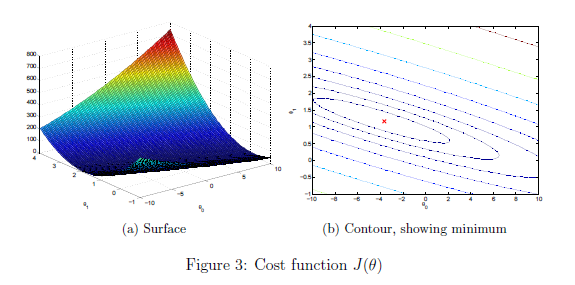

% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

    The purpose of these graphs is to show you that how $J(\theta)$ varies with changes in $\theta_0$ and $\theta_1$. The cost function $J(\theta)$ is bowl-shaped and has a global mininum. (This is easier to see in the contour plot than in the 3D surface plot). This minimum is the optimal point for $\theta_0$ and $\theta_1$, and each step of gradient descent moves closer to this point.

## Optional Exercises:

If you have successfully completed the material above, congratulations! You now understand linear regression and should able to start using it on your own datasets. For the rest of this programming exercise, we have included the following optional exercises. These exercises will help you gain a deeper understanding of the material, and if you are able to do so, we encourage you to complete them as well.

## 3. Linear regression with multiple variables

In this part, you will implement linear regression with multiple variables to predict the prices of houses. Suppose you are selling your house and you want to know what a good market price would be. One way to do this is to first collect information on recent houses sold and make a model of housing prices.

    The file `ex1data2.txt` contains a training set of housing prices in Portland, Oregon. The first column is the size of the house (in square feet), the second column is the number of bedrooms, and the third column is the price of the house. Run this section now to preview the data.

% Load Data
data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Print out some data points
% First 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

The remainder of this script has been set up to help you step through this exercise.

### 3.1 Feature Normalization

This section of the script will start by loading and displaying some values from this dataset. By looking at the values, note that house sizes are about 1000 times the number of bedrooms. When features differ by orders of magnitude, first performing feature scaling can make gradient descent converge much more quickly.

    Your task here is to complete the code in `featureNormalize.m` to:

- Subtract the mean value of each feature from the dataset.

- After subtracting the mean, additionally scale (divide) the feature values by their respective "standard deviations".

The standard deviation is a way of measuring how much variation there is in the range of values of a particular feature (most data points will lie within $\pm 2$ standard deviations of the mean); this is an alternative to taking the range of values (*max - min*). In MATLAB, you can use the `std` function to compute the standard deviation. For example, inside `featureNormalize.m`, the quantity `X(:,1)` contains all the values of $x_1$ (house sizes) in the training set, so `std(X(:,1))` computes the standard deviation of the house sizes. At the time that `featureNormalize.m` is called, the extra column of 1's corresponding to $x_0 = 1$ has not yet been added to `X` (see the code below for details).

    You will do this for all the features and your code should work with datasets of all sizes (any number of features / examples). Note that each column of the matrix `X` corresponds to one feature. When you are finished with `featureNormailize.m`, run this section to normailze the features of the housing dataset.

% Scale features and set them to zero mean
[X, mu, sigma] = featureNormalize(X);

**Implementation Note: **When normalizing the features, it is important to store the values used for normalization - the mean value and the standard deviation used for the computations. After learning the parameters from the model, we often want to predict the prices of houses we have not seen before. Given a new `x` value (living room area and number of bedrooms), we must first normalize `x` using the mean and standard deviation that we had previously computed from the training set.

#### Add the bias term

Now that we have normailzed the features, we again add a column of ones corresponding to $\theta_0$ to the data matrix `X``.`

% Add intercept term to X
X = [ones(m, 1) X];

### 3.2 Gradient Descent

Previously, you implemented gradient descent on a univariate regression problem. The only difference now is that there is one more feature in the matrix `X`. The hypothesis function and the batch gradient descent update rule remain unchanged.

    You should complete the code in `computeCostMulti.m` and `gradientDescentMulti``.m `to implement the cost function and gradient descent for linear regression *with multiple variables*. If your code in the previous part (single variable) already supports multiple variables, you can use it here too.

Make sure your code supports any number of features and is well-vectorized. You can use the command `size(X,2)` to find out how many features are present in the dataset.

    We have provided you with the following starter code below that runs gradient descent with a particular learning rate (`alpha`). Your task is to first make sure that your functions `computeCost` and `gradientDescent` already work with this starter code and support multiple variables.  

**Implementation Note: **In the multivariate case, the cost function can also be written in the following vectorized form:


$$J(\theta)=\frac{1}{2m}\left(X\theta-\vec{y}\right)^T\left(X\theta-\vec{y}\right)$$


where


$$X=\left\lbrack \begin{array}{c}
{-\;\left(x^{\left(1\right)} \right)}^T -\\
{-\;\left(x^{\left(2\right)} \right)}^T -\\
\vdots \;\\
{-\;\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\vec{y} =\left\lbrack \begin{array}{c}
y^{\left(1\right)} \\
y^{\left(2\right)} \\
\vdots \;\\
y^{\left(m\right)} 
\end{array}\right\rbrack$$


The vectorized version is efficient when you're working with numerical computing tools like MATLAB. If you are an expert with matrix operations, you can prove to yourself that the two forms are equivalent.

% Run gradient descent
% Choose some alpha value
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

Finally, you should complete and run the code below to predict the price of a 1650 sq-ft, 3 br house using the value of `theta` obtained above. 

**Hint:** At prediction, make sure you do the same feature normalization. Recall that the first column of `X` is all ones. Thus, it does not need to be normalized.

% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================

features = [1650 3]; % Enter your price formula here
features = (features - mu) ./ sigma
features = [ones(1, 1) features];

price = features * theta
% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

#### **3.2.1 Optional (ungraded) exercise: Selecting learning rates**

In this part of the exercise, you will get to try out dierent learning rates for the dataset and find a learning rate that converges quickly. You can change the learning rate by modifying the code below and changing the part of the code that sets the learning rate.

    The code below will call your `gradientDescent` function and run gradient descent for about 50 iterations at the chosen learning rate. The function should also return the history of $J(\theta)$ values in a vector `J`. After the last iteration, the code plots the `J` values against the number of the iterations. If you picked a learning rate within a good range, your plot should look similar Figure 4 below. 

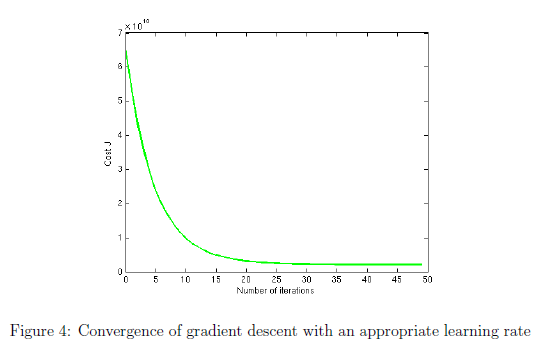

    If your graph looks very different, especially if your value of $J(\theta)$ increases or even blows up, use the control to adjust your learning rate and try again. We recommend trying values of the learning rate on a log-scale, at multiplicative steps of about 3 times the previous value (i.e., 0.3, 0.1, 0.03, 0.01 and so on). You may also want to adjust the number of iterations you are running if that will help you see the overall trend in the curve.

**Implementation Note:** If your learning rate is too large, $J(\theta)$ can diverge and 'blow up', resulting in values which are too large for computer calculations. In these situations, MATLAB will tend to return `NaNs`. `NaN` stands for 'not a number' and is often caused by undefined operations that involve $\pm \;\infty$.

**MATLAB Tip:** To compare how different learning learning rates affect convergence, it's helpful to plot `J` for several learning rates on the same figure. In MATLAB, this can be done by performing gradient descent multiple times with a `hold on` command between plots. Make sure to use the `hold off` command when you are done plotting in that figure. Concretely, if you've tried three different values of `alpha` (you should probably try more values than this) and stored the costs in `J1`, `J2` and `J3`, you can use the following commands to plot them on the same figure:

    The final arguments `'b'`,`'r'`, and `'k``'` specify different colors for the plots. If desired, you can use this technique and adapt the code below to plot multiple convergence histories in the same plot. 

% Run gradient descent:
% Choose some alpha value
alpha = 0.3;
num_iters = 50;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[~, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Plot the convergence graph
plot(1:num_iters, J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

Notice the changes in the convergence curves as the learning rate changes. With a small learning rate, you should find that gradient descent takes a very long time to converge to the optimal value. Conversely, with a large learning rate, gradient descent might not converge or might even diverge! 

    Using the best learning rate that you found, run the section of code below, which will run gradient descent until convergence to find the final values of $\theta$. Next, use this value of $\theta$ to predict the price of a house with 1650 square feet and 3 bedrooms. You will use value later to check your implementation of the normal equations. Don't forget to normalize your features when you make this prediction!

% Run gradient descent
% Replace the value of alpha below best alpha value you found above
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

% Estimate the price of a 1650 sq-ft, 3 br house. You can use the same
% code you entered ealier to predict the price
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

### 3.3 Normal Equations

In the lecture videos, you learned that the closed-form solution to linear regression is


$$\theta = \left(X^T X\right)^{-1} X^T \vec{y} $$


    Using this formula does not require any feature scaling, and you will get an exact solution in one calculation: there is no "loop until convergence" like in gradient descent.

    Complete the code in `normalEqn.m` to use the formula above to calculate $\theta$, then run the code in this section. Remember that while you don't need to scale your features, we still need to add a column of 1's to the `X` matrix to have an intercept term ($\theta_0$) . Note that the code below will add the column of 1's to `X` for you.

% Solve with normal equations:
% Load Data
data = csvread('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f\n%f', theta(1),theta(2),theta(3));

**Optional (ungraded) exercise: **Now, once you have found $\theta$ using this method, use it to make a price prediction for a 1650-square-foot house with 3 bedrooms. You should find that gives the same predicted price as the value you obtained using the model fit with gradient descent (in Section 3.2.1).

% Estimate the price of a 1650 sq-ft, 3 br house. 
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price forumla here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using normal equations):\n $%f', price);     

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

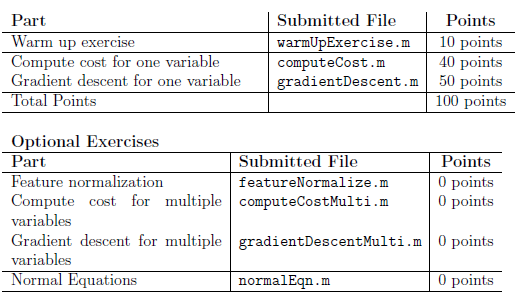

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.